clear all; close all; clc; rng(1);

## Function to be learned

g = @(p) 1 + sin(2 * pi / 4 * p);
p = linspace(-2, 2, 200);

## Neural Network Architecture

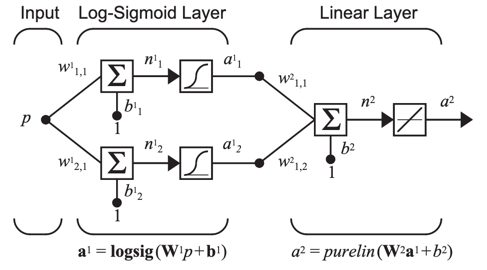

f  = {
        @(n) logsig(n)
        @(n) purelin(n)
     };
df = {
        @(n) logsig(n) .* (1 - logsig(n))
        @(n) ones(size(n))
     };

twodi_TrainingData = twodi_TrainingData_Class();

for i = 1 : 1 : size(p, 2)
    twodi_TrainingData.addTrainingSample("input", p(:, i), "output", g(p(:, i)));
end
Q = twodi_TrainingData.getNrOfTrainingSamples();

NR_OF_EPOCHS = 1e3;



h = waitbar(0, 'Training progress...');
ITER = struct([]); 
for epoch = 1 : 1 : NR_OF_EPOCHS

    ITER(epoch).network = twodi_NetworkMLP_Class(                           ...
                                                 "nrOfLayers" , 2         , ...
                                                 "nrOfInputs" , size(p, 1), ...
                                                 "nrOfNeurons", [3, 1]    , ...
                                                 "actvnFcn"   , f         , ...
                                                 "dActvnFcn"  , df          ...
                                                );
    if(epoch >= 2)
        ITER(epoch).network.setWeigths(ITER(epoch - 1).network.getWeights);
        ITER(epoch).network.setBiases(ITER(epoch - 1).network.getBiases);
    end
    
    M = ITER(epoch).network.getNrOfLayers;
    %Every Np epochs, restart the conjugate gradient to steepest descent
    Np = 0; for m = 1 : 1 : M, Np = Np + numel(ITER(1).network.getWeight(m)) + numel(ITER(1).network.getBias(m)); end

**            Compute the gradients of performance index w.r.t. W and b**

    dFhat_dW = cell(M, 1); dFhat_db = cell(M, 1); 
    for m = 1 : 1 : M
        dFhat_dW{m} = zeros(size(ITER(epoch).network.getWeight(m)));
        dFhat_db{m} = zeros(size(ITER(epoch).network.getBias(m)));
    end

    for q = 1 : 1 : Q

        [p_q, t_q] = twodi_TrainingData.getTrainingSample(q);
        [~, a]     = ITER(epoch).network.evaluate(p_q);
        s          = ITER(epoch).network.getBackprop__dF_dn(t_q);

        for m = 1 : 1 : M
            if(m == 1)
                dFhat_dW{m} = dFhat_dW{m} + s{m} * p_q';
            else
                dFhat_dW{m} = dFhat_dW{m} + s{m} * a{m - 1}';
            end
            dFhat_db{m} = dFhat_db{m} + s{m};
        end

    end

    for m = 1 : 1 : M
        dFhat_dW{m} = 1 / Q * dFhat_dW{m};
        dFhat_db{m} = 1 / Q * dFhat_db{m};

        ITER(epoch).network.setdF_dW(m, dFhat_dW{m});
        ITER(epoch).network.setdF_db(m, dFhat_db{m});
    end

            **Compute the direction**

    dW = cell(M, 1); db = cell(M, 1);
    if((epoch == 1) || (mod(epoch - 1, Np) == 0))
        for m = 1 : 1 : M
            dW{m} = -dFhat_dW{m};
            db{m} = -dFhat_db{m};
        end
    else
        
        beta = (ITER(epoch).network.getGradF_dx' * ITER(epoch).network.getGradF_dx) / (ITER(epoch - 1).network.getGradF_dx' * ITER(epoch - 1).network.getGradF_dx);

        for m = 1 : 1 : M
            dW{m} = -dFhat_dW{m} + beta * ITER(epoch - 1).dW{m};
            db{m} = -dFhat_db{m} + beta * ITER(epoch - 1).db{m};
        end
    end
    ITER(epoch).dW = dW; ITER(epoch).db = db;

**            Compute the variable learning step**

    F_sym = cell(Q, 1); n_sym = cell(Q ,1); a_sym = cell(Q, 1);
    for q = 1 : 1 : Q

        [p_q, t_q] = twodi_TrainingData.getTrainingSample(q);

        for m = 1 : 1 : M 

            W = ITER(epoch).network.getWeight(m);
            b = ITER(epoch).network.getBias(m);

            if(m == 1)
                n_sym{m} = @(alpha) (W + alpha * dW{m}) * p_q                 + (b + alpha * db{m});
            else
                n_sym{m} = @(alpha) (W + alpha * dW{m}) * a_sym{m - 1}(alpha) + (b + alpha * db{m});
            end
            a_sym{m} = @(alpha) f{m}(n_sym{m}(alpha));
        end

        % Symbolic network error
        e_sym = @(alpha) (t_q - a_sym{M}(alpha));

        % Symbolic cost
        F_sym{q} = @(alpha) e_sym(alpha)' * e_sym(alpha);

    end

    alpha = twodi_GoldenSectionSearch(@(alpha) sum(cellfun(@(F_k) F_k(alpha), F_sym)), 0, 1);

**            Batch update**

    for m = 1 : 1 : M

        W_new = ITER(epoch).network.getWeight(m) + alpha * dW{m};
        b_new = ITER(epoch).network.getBias(m)   + alpha * db{m};

        ITER(epoch).network.setWeigth(m, W_new);
        ITER(epoch).network.setBias(m, b_new);
    end

    ITER(epoch).alpha = alpha;

            **Compute the squared-error performance index**

    F_k = 0;
    for q = 1 : 1 : Q
        [p_q, t_q] = twodi_TrainingData.getTrainingSample(q);
        [~, a]     = ITER(epoch).network.evaluate(p_q);
        e_q = t_q - a{M};
        F_k = F_k + e_q' * e_q;
    end
    
    F_k = (1 / Q) * F_k;
    ITER(epoch).F = F_k;
    ITER(epoch).index = epoch;

            **Update progress bar**

    waitbar(epoch / NR_OF_EPOCHS, h, sprintf('Training progress: %.1f%%', 100 * epoch / NR_OF_EPOCHS));
end
close(h);

## Validation

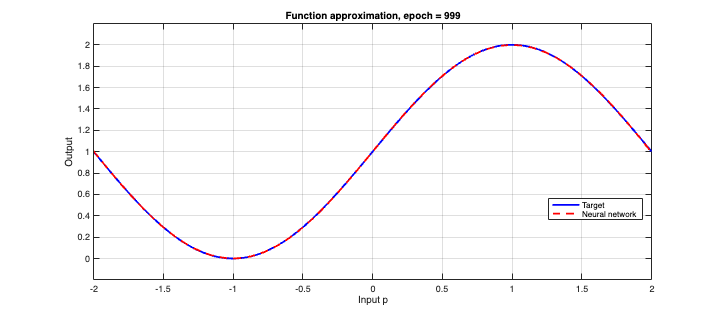

t_real = g(p); figure('Position', [100 100 800 350]);

h1 = plot(p, t_real, 'b-', 'LineWidth', 2); hold on;
h2 = plot(p, nan(size(p)), 'r--', 'LineWidth', 2);

grid on; xlabel('Input p'); ylabel('Output'); legend({'Target', 'Neural network'}, 'Location', 'best');
xlim([p(1), p(end)]); ylim([min(t_real) - 0.2, max(t_real) + 0.2]);
for epoch = round(linspace(1, length(ITER), 10))

    network = ITER(epoch).network;
    y = zeros(size(p));
    for q = 1 : 1 : length(p)

        [~, a] = network.evaluate(p(q));
        y(q) = a{end};

    end

    set(h2, 'YData', y);
    title(sprintf('Function approximation, epoch = %d', epoch - 1));

    drawnow; pause(0.1);
end

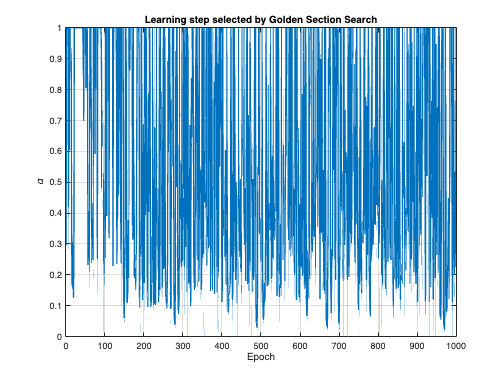

figure; plot([ITER.alpha], 'LineWidth', 1.5); grid on; xlabel('Epoch'); ylabel('\alpha'); title('Learning step selected by Golden Section Search');

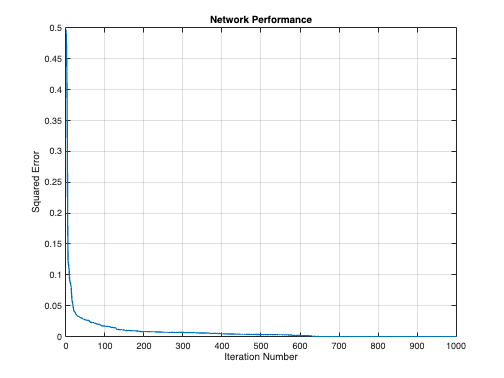

figure; plot([ITER.index], [ITER.F], 'LineWidth', 1.5); grid on; xlabel('Iteration Number'); ylabel('Squared Error'); title('Network Performance');